## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for complex formation (4 species) is already implemented with the name as ``func_gold90``, provided by Prof. Baum, saved in the path for models as above.

Parameters:

% Parameters from supplementary material
s_star = [0.3920, 1.6456]';  % Initial concentrations
klin = [1, 7.3 * 0.4, 65, 500, 1, 10]; 
knonlin = [1, 2, 0.9, 2, 2, 4];


## 2. Result reproduction

### Temporal dynamics

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 2.64, 265);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_gold90(t,x,klin, knonlin), tspan, s_star, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

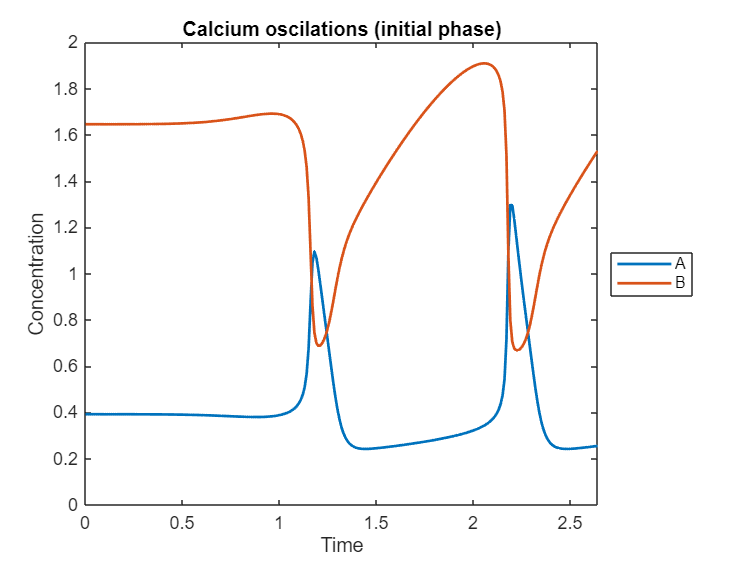

figure;
plot(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,2.64]);
ylim([0,2]);
title('Calcium oscilations (initial phase)');
legend('A','B','Location','eastoutside'); % southeast

Now, when the system have stable trajectories, draw temporal dynamics for t=[0, 3].

tspan = linspace(0, 3, 3001);
[t,sol] = ode15s(@(t,x) func_gold90(t,x,klin, knonlin), tspan, s_star_2, opts);

Plot

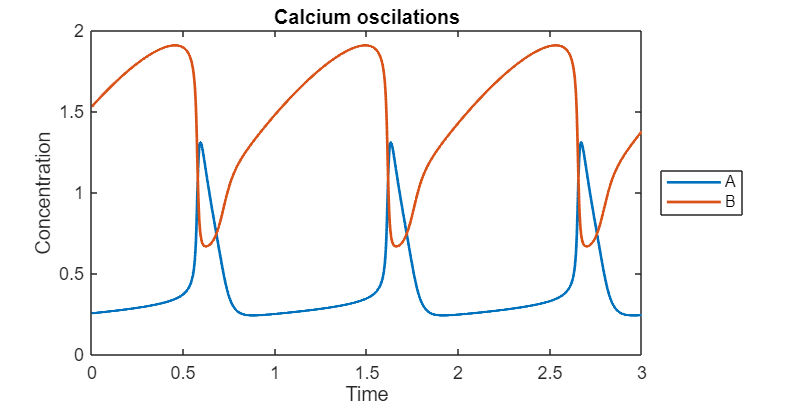

figure('Position',[100 100 600 300]);
plot(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,3]);
ylim([0,2]);
title('Calcium oscilations');
legend('A','B','Location','eastoutside'); % southeast

### **Detect loop structures:**

[loop_rep, loop_rep_index, jac_rep, jac_rep_index] =find_loops_vset(@(x)func_gold90(1,x,klin,knonlin),sol',10);
disp(loop_rep)

    {3×3 table}    {3×3 table}    {3×3 table}



disp(loop_rep_index)

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

loop_id = loop_rep_index(:);
disp('loop_rep_index and time_vec must match.'); disp(numel(loop_id)); disp(numel(t));

loop_rep_index and time_vec must match.
        3001

        3001



% Find segment boundaries where loop_id changes
change_idx = [1; find(diff(loop_id) ~= 0) + 1; numel(loop_id) + 1];

nSeg = numel(change_idx) - 1;
t_start = zeros(nSeg,1);
t_end   = zeros(nSeg,1);
seg_id  = zeros(nSeg,1);

for s = 1:nSeg
    i1 = change_idx(s);
    i2 = change_idx(s+1) - 1;
    t_start(s) = t(i1);
    t_end(s)   = t(i2);
    seg_id(s)  = loop_id(i1);
end

transition_times = t_end(1:end-1);


Plot:

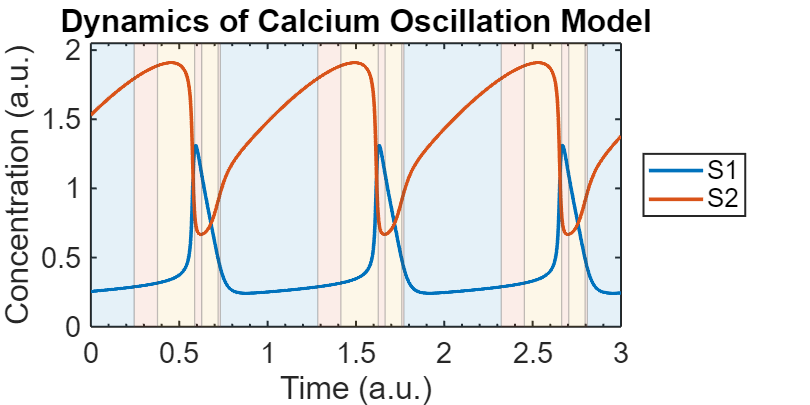

figure('Color','w', 'Position',[100 100 600 300]); hold on;

% Set x-limits early (so patches cover the right region)
xlim([0 3]);  % adapt as needed
xlabel('Time (a.u.)');
ylabel('Concentration (a.u.)');
title('Dynamics of Calcium Oscillation Model');

% Get y-limits from data, then draw patches spanning full height
ymin = 0; % min(sol(:));
ymax = 2.05; % max(sol(:));
ylim([ymin ymax]);

% Colors for loop structures (categorical palette)
uID = unique(seg_id, 'stable');
cmap = lines(numel(uID));  % quick palette; swap to brewermap if you prefer

% Background bands (behind lines): patch rectangles
for s = 1:nSeg
    cidx = find(uID == seg_id(s), 1);
    x = [t_start(s) t_end(s)   t_end(s)   t_start(s)];
    y = [ymin       ymin       ymax       ymax];
    patch(x, y, cmap(cidx,:), ...
        'EdgeColor','none', ...
        'FaceAlpha',0.10, ...
        'HandleVisibility','off'); % keep legend clean
end

% Vertical transition lines
for tt = transition_times(:)'
    xline(tt, '-', ...
        'Color', [0.3 0.3 0.3], ...
        'LineWidth', 0.7, ...
        'Alpha', 0.35, ...
        'HandleVisibility','off');
end

% Trajectories (equivalent to geom_line)
nSpec = size(sol,2);
spec_colors = lines(nSpec);  % replace with your own colors vector if you have one
h = gobjects(nSpec,1);

for j = 1:nSpec
    h(j) = plot(t, sol(:,j), 'LineWidth', 2, 'Color', spec_colors(j,:));
end

% Axis ticks like your ggplot scale_x_continuous
xticks(0:0.5:3);
xlim([0 3]);

% Styling similar to theme_minimal + border
set(gca, ...
    'FontSize', 16, ...
    'Box', 'on', ...
    'LineWidth', 1.1, ...
    'XMinorTick', 'on');
grid off;

% Legend for species (like scale_colour_manual)
legend(h, compose('S%d', 1:nSpec), 'Location','eastoutside');

### **Re-run**

[loop_rep, loop_rep_index, jac_rep, jac_rep_index] =find_loops_vset(@(x)func_gold90(1,x,klin,knonlin),sol',10);
disp(jac_rep);

    {2×2 double}    {2×2 double}    {2×2 double}



### **Loop structures**

**Loop 1:**

disp(loop_summary(loop_rep{1}));

                length_1    length_2
                ________    ________

    total          2           1    
    negative       2           0    
    positive       0           1    



**Loop 2:**

disp(loop_summary(loop_rep{2})); 

                length_1    length_2
                ________    ________

    total          2           1    
    negative       2           1    
    positive       0           0    



**Loop 3:**

disp(loop_summary(loop_rep{3}));

                length_1    length_2
                ________    ________

    total          2           1    
    negative       1           1    
    positive       1           0    



### **Jacobian matrices:**

disp(jac_rep{1});

    -1     1
     1    -1



disp(jac_rep{2});

    -1     1
    -1    -1



disp(jac_rep{3});

     1     1
    -1    -1



## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_6_calcium_oscillations.mlx", "MATLAB/model_6_calcium_oscillations.pdf")

path = 'MATLAB\model_6_calcium_oscillations.pdf'

mdfile = export("MATLAB/model_6_calcium_oscillations.mlx","MATLAB/model_6_calcium_oscillations.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_6_calcium_oscillations.md'